function energies = soft_sphere_simulation(dt, total_time, N, sigma, kint, kcenter, mass)
    % Default values if not provided
    if nargin < 7
        mass = 1;
    end
    if nargin < 6
        kcenter = 0.1;
    end
    if nargin < 5
        kint = 1;
    end
    if nargin < 4
        sigma = 1;
    end
    if nargin < 3
        N = 10;
    end
    if nargin < 2
        total_time = 100;
    end
    if nargin < 1
        dt = 0.01;
    end

    % Initialize positions and velocities
    r = 10 * rand(N, 3);
    v = randn(N, 3);
    
    r0 = [0, 0, 0];
    
    t = 0;
    energies = [];
    while t < total_time
        F = calculate_forces(r, r0, N, sigma, kint, kcenter);
        
        % Update
        r_new = r + v * dt + 0.5 * F / mass * dt^2;
        F_new = calculate_forces(r_new, r0, N, sigma, kint, kcenter);
        v = v + 0.5 * (F + F_new) / mass * dt;
        r = r_new;
        
        % Calculate and store total energy
        H = calculate_energy(r, v, r0, N, sigma, kint, kcenter, mass);
        energies = [energies; H];
        
        t = t + dt;
    end
end

function F = calculate_forces(r, r0, N, sigma, kint, kcenter)
    F = zeros(N, 3);
    
    % interaction forces
    for i = 1:N
        for j = i+1:N
            rij = r(j,:) - r(i,:);
            distance = norm(rij);
            if distance < sigma
                F_magnitude = kint * (sigma - distance);
                F(i,:) = F(i,:) + F_magnitude * rij / distance;
                F(j,:) = F(j,:) - F_magnitude * rij / distance;
            end
        end
    end
    
    % Central forces
    for i = 1:N
        r_to_center = r(i,:) - r0;
        F(i,:) = F(i,:) - kcenter * r_to_center;
    end
end

function H = calculate_energy(r, v, r0, N, sigma, kint, kcenter, mass)
    T = 0.5 * mass * sum(sum(v.^2));
    
    % Particle interaction potential
    V_int = 0;
    for i = 1:N
        for j = i+1:N
            rij = r(j,:) - r(i,:);
            distance = norm(rij);
            if distance < sigma
                V_int = V_int + 0.5 * kint * (sigma - distance)^2;
            end
        end
    end
    
    % Central potential
    V_ctr = 0;
    for i = 1:N
        r_to_center = r(i,:) - r0;
        V_ctr = V_ctr + 0.5 * kcenter * norm(r_to_center)^2;
    end
    
    H = T + V_int + V_ctr;
end

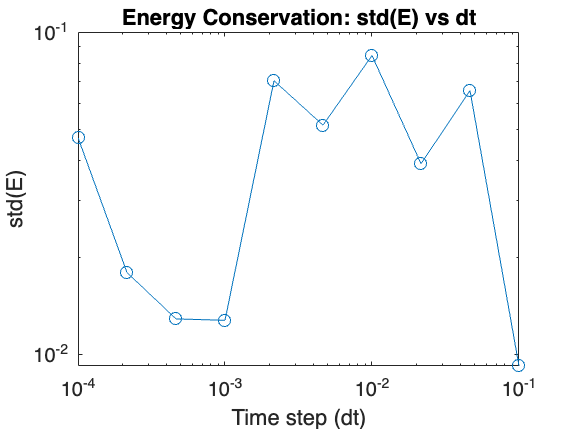

% Parameters
total_time = 100;
N = 10;
sigma = 1;
kint = 1;
kcenter = 0.1;
mass = 1;

% Range of dt values to test
dt_values = logspace(-5, -1, 40);
std_E = zeros(size(dt_values));

% Run simulations for different dt values
for i = 1:length(dt_values)
    energies = soft_sphere_simulation(dt_values(i), total_time, N, sigma, kint, kcenter, mass);
    std_E(i) = std(energies);
end

% Plot log-log
figure;
loglog(dt_values, std_E, 'o-');
xlabel('Time step (dt)');
ylabel('std(E)');
title('Energy Conservation: std(E) vs dt');


% Fit a line
p = polyfit(log(dt_values), log(std_E), 1);
disp(['Slope of log-log plot: ', num2str(p(1))]);

Slope of log-log plot: 0.041911
